# Simulation-based investigation of evolutionary stability of extortionate zero-determinant strategies

*Christoph Siebenbrunner*

*Term Project - DPhil Mathematics Broadening Requirement*

*Computational Game Theory (MT 2016)*

## Abstract

Zero-determinant (ZD) strategies are a recently discovered class of strategies for the iterated prisoner's dilemma and similar 2-player games with highly interesting properties. A particularly interesting variety of such ZD strategies allow one player to set its own score to a multiplicative factor of her opponent's score. If this factor is chosen to be greater than one, such strategies are called extortionate strategies and will outcompete any opponent unless he chooses to defect fully (in which case both player's payoffs are equal). While such strategies are obviously superior in any two-person player game, they perform less stellar in evolutionary settings because they start performing poorly once they gain a significant share of the population and are matched against their own kind. In this project I replicate those findings using an agent-based simulation pitching extortionate ZD strategies against different opponents, i.e. AllC-, AllD-, Tit-for-Tat, Random and Pavlov strategies. The simulation results confirm the theoretical results.

## Introduction

Press and Dyson (2012) introduced a new class of strategies for the iterated prisoner's dilemma (IPD) as well as for other types of similar two-player games. In their seminal article the authors make at least three discoveries about the IPD:

- There exists a class of (zero-determinant, ZD) strategies which allow any player to unilaterally enforce a linear relationship between the two player's payoffs in the stationary state. This allows i.a. for one player to demand an extortionate share of payoffs in the game.

- For any two strategies with different memory size, there exists an equivalent simpler version of the longer-memory strategy with the same memory size as the shorter memory strategy.

- The nature of the IPD game changes fundamentally as soon as at least one player has knowledge of ZD strategies. In the case where e.g. one player has knowledge about ZD strategies and demands and extortionate share, and the other player has at least a Theory of Mind of its opponent, the IPD is reduced to an ultimatum game.

While the article by Press and Dyson (2012) only deals with the case of one-round memory strategy, (2) implies that their findings indeed hold for IPD games in general. As mentioned in (3), knowledge of ZD strategies fundamentally changes the nature of the IPD game.

Regarding the major contribution (1), Press and Dyson (2012) show that it is possible for one player to unilaterally enforce a linear relation between their two respective payoffs $s_x ,s_y$ in the stationary stationary only by setting his own strategy vector $p$ independent of the other players strategy:


$$\alpha s_x +\beta s_y +\gamma =0$$


This gives the player at least two possibilities: he can set his opponent's score to a fixed value, or he can set his own score to be multiplicative factor of his opponent's score (setting his own score is not possible, as shown by Press and Dyson (2012)). The latter approach is particularly interesting, as it is possible to set this factor to a value $>1$ and thus demand and extortionate share. This is achieved by solving the following system of equations:


$$p'=\Phi \left(S_x −P−\chi \left(S_y −P\right)\right)$$


Where $p'=\left(p_1 −1,p_{2\text{ }} −2,p_3 ,p_4 \right)$ contains the probabilities constituting player X's strategy, $S_x =\left(R,S,T,P\right)$ and $S_y =\left(R,T,S,P\right)$ are the payoff vectors for the two players and $\chi \text{ }$ governs the extortion factor through (Hilbe et al. 2013):


$$s_x =\chi \text{ }\left(s_y −P\right)+P$$


The above equations give formulae as a function of $\Phi \text{ }$ and $\chi \text{ }$for player X's probabilities as well as an upper bound for $\Phi \text{ }$ as a function of $\chi \text{ }$. Furthermore $\Phi >0$ and $\chi \text{ }\ge 1$. The well-known Tit-for-Tat-strategy can thus be seen to be a corner solution of a ZD strategy with $\chi =1$ and $\Phi$ taking its maximum allowed value 0.2 (Press and Dyson 2012).

## Demonstration

Press and Dyson (2012) show that when one player plays a ZD strategy then the payoff for both players is maximized if the other player chooses to cooperate unconditionally. Using the standard IPD payoffs $\left(R,S,T,P\right)=\left(3,0,5,1\right)$ the maximum expected payoffs for the two players are:


$$s_x =\frac{2+13\chi \text{ }}{2+3\chi \text{ }}$$
    
$$s_y =\frac{12+3\chi \text{ }}{2+3\chi \text{ }}$$


Looking at an IPD simulation of a ZD against a cooperative strategy that the ZD player is indeed able to demand an extortionate share of payoffs:

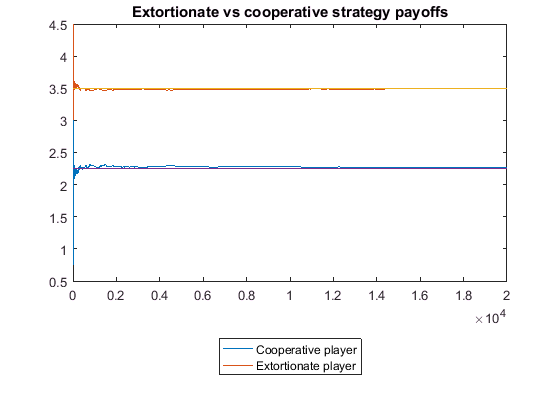

Phi = 0.1;
chi = 2;
NRounds = 20000;
PDGame = Game([3 0;5 1]);
ExtPlayer = PlayerExtortionate(Phi,chi);
AllCPlayer = PlayerAllC;
[ExtPlayer,AllCPlayer] = PDGame.playNRounds(NRounds,ExtPlayer,AllCPlayer);
figure
plot([AllCPlayer.AveragePayoffHistory ExtPlayer.AveragePayoffHistory])
title('Extortionate vs cooperative strategy payoffs')
legend({'Cooperative player' 'Extortionate player'},'Location','southoutside')
hold on
plot([0 NRounds],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
plot([0 NRounds],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])

We also see that the payoffs for both players converge to their theoretically predicted values:

disp({...
    'Payoff per strategy' 'Extortion' 'Cooperation' 'Ratio';
    'Simulation result:' ...
    ExtPlayer.AveragePayoff AllCPlayer.AveragePayoff ...
    ExtPlayer.AveragePayoff/AllCPlayer.AveragePayoff;
    'Theoretical prediction:' ...
    (2+chi*13)/(2+chi*3) (12+3*chi)/(2+3*chi) ...
    ((2+chi*13)/(2+chi*3))/((12+3*chi)/(2+3*chi)) })

    'Payoff per strategy'        'Extortion'    'Cooperation'    'Ratio' 
    'Simulation result:'         [   3.4912]    [     2.2632]    [1.5426]
    'Theoretical prediction:'    [   3.5000]    [     2.2500]    [1.5556]



If we compare the extortionate strategy against other strategies, we see that the payoffs for both players are indeed lower. For a defective, a tit-for-tat or another extortionate strategy these all converge to the P-payoff of constant mutual defection, thus giving the lowest possible solution of the $s_x$-expression in the introduction. The payoffs against a random (always cooperates with 50% probability) and a Pavlov player ("win-stay-lose-shift") both lie in between the maximum and the minimum value, where the payoffs for both players are still higher when playing against Pavlov. 

arrOpponents = {'PlayerAllC()' 'PlayerAllD()' ...
    'PlayerTitForTat()' 'PlayerRandom()' 'PlayerPavlov()'};
Games = cell(length(arrOpponents),1);

for i = 1:length(arrOpponents)
    strOpponent = arrOpponents{i};
    [tmpExtPlayer,tmpOpponent] = PDGame.playNRounds(NRounds,PlayerExtortionate(Phi,chi),eval(strOpponent));
    disp({ ...
    'Extortionate Player' [strOpponent(7:end-2) ' Player']
    tmpExtPlayer.AveragePayoff tmpOpponent.AveragePayoff})
end    

    'Extortionate Player'    'AllC Player'
    [             3.4773]    [     2.2841]



    'Extortionate Player'    'AllD Player'
    [             1.0000]    [     1.0002]



    'Extortionate Player'    'TitForTat Player'
    [             1.0012]    [          1.0012]



    'Extortionate Player'    'Random Player'
    [             2.4739]    [       1.7387]



    'Extortionate Player'    'Pavlov Player'
    [                  3]    [       1.9917]



This is due to the fact that both the random and the Pavlov strategy cooperate for many moves, whereas the others end up in an equilibrium of mutual defection. The Pavlov strategy will tend to cooperate even more often than the random strategy. The reason for this is that the extortionate strategy will cooperate after most moves following mutual cooperation and will always defect following mutual defection:

disp({'Extortion Strategy','c','d';'c',ExtPlayer.Strategy(1,1),ExtPlayer.Strategy(1,1);...
    'd',ExtPlayer.Strategy(2,1),ExtPlayer.Strategy(2,2)})

    'Extortion Strategy'    'c'         'd'     
    'c'                     [0.8000]    [0.8000]
    'd'                     [0.6000]    [     0]



This means that a game pitching the Pavlov against an extortionate strategy will see mutual cooperation for most moves, and whenever the ZD strategy defects, the game will quickly return to mutual cooperation thanks to Pavlov's "lose-shift" property. This makes the formal result of Dyson and Press (2012) evident that the best that one can do in order to maximize one's own score when playing against a zero-determinant strategy is to cooperate maximally.

Note: the initial move is not defined by the ZD strategy. As the authors (Press and Dyson 2012) remark, this move has no influence on the stationary payoff. I set the initial move to cooperation (rather than a random move) for better comparability. The same holds for the random player.

## Parameter sensitivity

**Number of rounds**

Visual inspection of the above chart shows rather fast speed of convergence. In the evolutionary simulation it is necessary to set the number of games that two players will engage in when they are matched against each other. Given limitations on available computing power, a smaller number of rounds than used above has to be chosen. If we look at the distribution of the average payoffs of each player after different numbers of rounds over 500 simulations, we see that the interquartile ranges do not decrease much after the first 100 rounds. Hence I will set the number of rounds played by two matched opponents in the evolutionary game to 100.

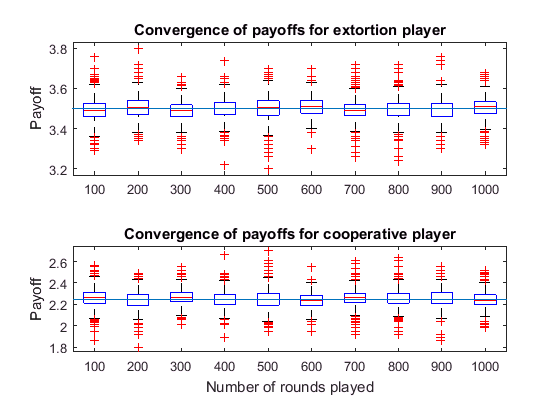

NIterations = 500;
NQueryPoints = 10;
QueryStep = 100;
NRounds = NQueryPoints*QueryStep;

matPayoffsExtPlayer = nan(NIterations,NQueryPoints);
matPayoffstmpAllCPlayer = nan(NIterations,NQueryPoints);
vecGrouping = repmat([QueryStep:QueryStep:NRounds]',NIterations,1);

parfor i=1:NIterations
    [tmpExtPlayer,tmpAllCPlayer] = PDGame.playNRounds(NRounds,PlayerExtortionate(Phi,chi),PlayerAllC);
    matPayoffsExtPlayer(i,:) = tmpExtPlayer.AveragePayoffHistory(QueryStep:QueryStep:NRounds);
    matPayoffstmpAllCPlayer(i,:) = tmpAllCPlayer.AveragePayoffHistory(QueryStep:QueryStep:NRounds);
end 

figure
subplot(2,1,1)
boxplot(matPayoffsExtPlayer(:),vecGrouping)
title('Convergence of payoffs for extortion player')
ylabel('Payoff')
hold on
plot([0 NRounds],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
hold off
subplot(2,1,2)
boxplot(matPayoffstmpAllCPlayer(:),vecGrouping)
ylabel('Payoff')
xlabel('Number of rounds played')
title('Convergence of payoffs for cooperative player')
hold on
plot([0 NRounds],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])

**Extortion Parameters**

Regarding the impact of the parameters $\Phi$ and $\chi$ we see that $\Phi$ has no influence over the payoffs whereas $\chi$ indeed is proportional to the extortion share of the ZD player. We see faster convergence for lower values of $\chi$ hence I will set it to a relatively modest extortion factor of $\chi =2$ for further runs. We also see that a higher $\phi$ improves convergence. The maximum allowed $\Phi$ for $\chi =2$ is 0.111, hence I will set $\Phi =0\ldotp 1$.

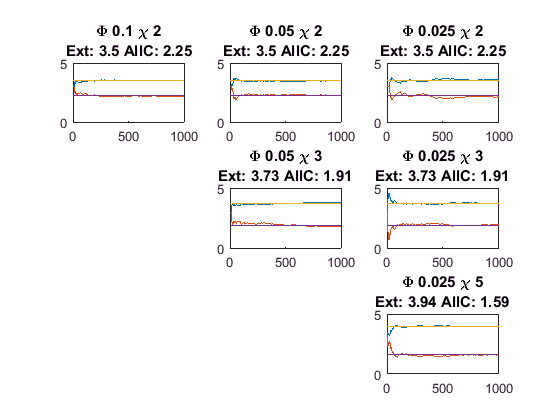

vecPhi = [0.1 0.05 0.025];
vecChi = [2 3 5];

figure 
for i = 1:9
    try
        Phi = vecPhi(mod(i-1,3)+1);
        chi = vecChi(ceil(i/3));
        
        ExtPlayer = PlayerExtortionate(Phi,chi);
        AllCPlayer = AllCPlayer.resetHistory;
        [ExtPlayer,AllCPlayer] = PDGame.playNRounds(1000,ExtPlayer,AllCPlayer);
        
        subplot(3,3,i)
        plot([ExtPlayer.AveragePayoffHistory AllCPlayer.AveragePayoffHistory])
        hold on
        plot([0 1000],[(2+chi*13)/(2+chi*3) (2+chi*13)/(2+chi*3)])
        plot([0 1000],[(12+3*chi)/(2+3*chi) (12+3*chi)/(2+3*chi)])
        ylim([0 5])
        title(['\Phi ' num2str(Phi) ' \chi ' num2str(chi) newline 'Ext: ' ...
            num2str(round(((2+chi*13)/(2+chi*3))*100)/100) ' AllC: ' ...
            num2str(round(((12+3*chi)/(2+3*chi))*100)/100)])
    end
end

## Evolutionary dynamics

Evolutionary dynamics are implemented as follows. A population is initialized with equal shares of two types of players. In every generation, each player is matched with a random opponent (uniform over all other players except for himself) and they play a fixed number of games against each other. Hence in every generation each player will play at least one and on average two games. The scores of all games are kept and averaged over the number of games played in that generation. These payoffs are used to compute the average score per player type (averaged over individuals). The change in shares of player types is governed by standard discrete-time replicator dynamics (see e.g. Bauso 2016). Payoffs are not carried into the next generation.

PopulationSize = 100;
NumberOfGames = 100;
NumberOfGenerations = 10000;

arrOpponents = {'PlayerAllC()' 'PlayerAllD()' ...
    'PlayerTitForTat()' 'PlayerRandom()' 'PlayerPavlov()'};
Games = cell(length(arrOpponents),1);

parfor i = 1:length(arrOpponents)
    strOpponent = arrOpponents{i};
    NewGame = Game([3 0;5 1]);
    NewGame = NewGame.createPopulation(PopulationSize,strOpponent,0.5,...
        'PlayerExtortionate(0.1,2)',0.5);
    NewGame = NewGame.runNGenerationTournament(NumberOfGenerations,NumberOfGames);
    NewGame.plotPopulationHistory(['Extortionate against ' strOpponent(7:end-2) ' player'])
    Games{i} = NewGame;
end

## Discussion

As was noted by Adami and Hintze (2013), ZD strategies, while being clearly superior in 2-player games, perform less stellar in an evolutionary setting. 

## References

Adami, C., & Hintze,  A. (2013). Evolutionary instability of zero-determinant strategies  demonstrates that winning is not everything. *Nature communications*, *4:2193*.

Bauso, D. (2016). *Game theory with engineering applications*. Society for Industrial and Applied Mathematics.

Hilbe, C., Nowak, M. A., & Sigmund, K. (2013). Evolution of extortion in iterated prisoner’s dilemma games. *Proceedings of the National Academy of Sciences*, *110*(17), 6913-6918.

Press, W. H., &  Dyson, F. J. (2012). Iterated Prisoner’s Dilemma contains strategies  that dominate any evolutionary opponent. *Proceedings of the National Academy of Sciences*, *109*(26), 10409-10413.

## Annex: UML diagram of implementation